# Introduction to Linear regression

## Testing commands

% result = runtests('livescript_regressionTest.mlx')

## Initialisation

("Data initialised ...")

ans = "Data initialised ..."

x = [0.8; 1.4; 2.7; 3.8; 4.8; 5];
y = [0.69; 1.0; 2.02; 2.39; 2.34; 2.83];

## Calculate Linear Regession and Plot

disp("Linear regression ...")

Linear regression ...


phi_lin = regression_linear(x,y)

phi =     0.4460
    0.4646


phi_lin =     0.4460
    0.4646


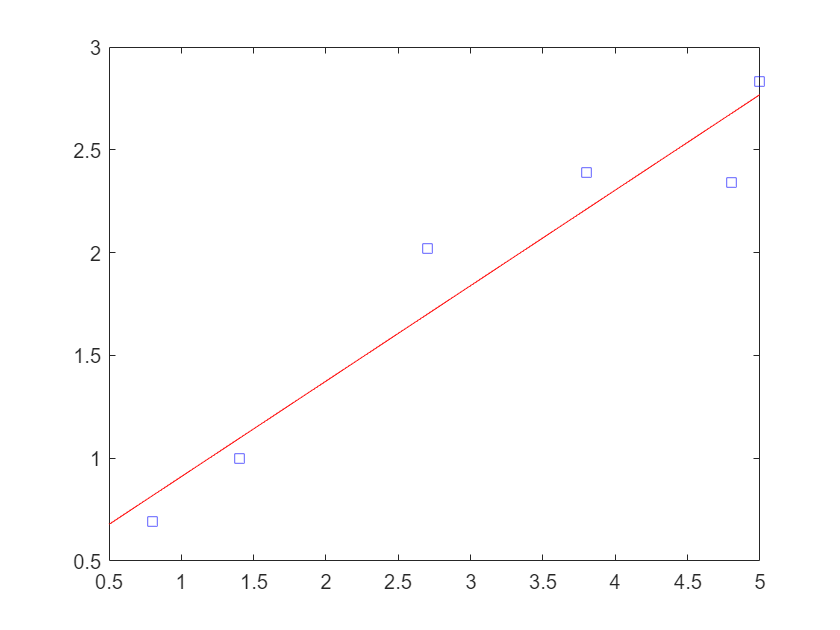

plot(x,y,'bs', [0.5 5], phi_lin(1) + phi_lin(2)*[0.5 5], '-r');

## Multiple Parameters

disp("Multi parameter regression ...")

Multi parameter regression ...


N = length(x);
X = [ones(N,1), x];
Y = y;
phi_mult = least_minimum_square(X,Y)

phi =     0.4460
    0.4646


phi_mult =     0.4460
    0.4646


## Test

assert(abs(phi_mult(1) - phi_lin(1)) <= 1e-10, 'methods are not the same')
